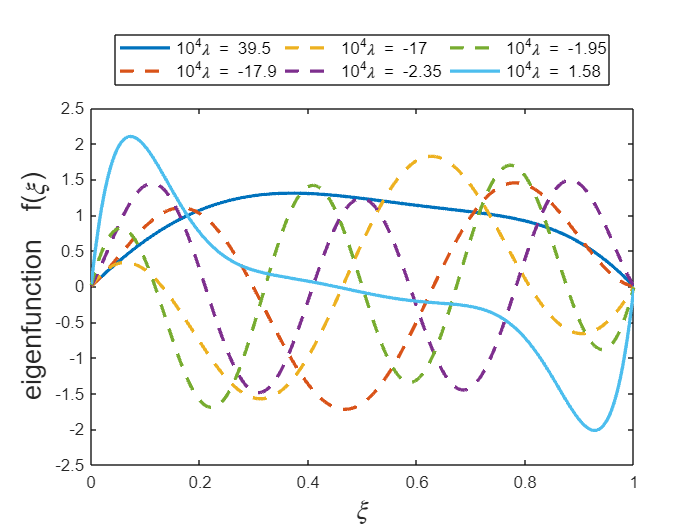

N = 1000;
eta = exp(-pi*1i/8);

xi_values = (2*(1:N) - 1)./(2*N);
Sp = 3;
k = 0.72;

        G_prime = zeros(N, N);
        cosines = zeros(N, N);
        sines = zeros(N, N);
        
        
        %phi_of_xi = zeros(1, length(xi_values));
        phi_of_xi = 2*pi*k*xi_values;
        
        
        for b = 1:N
            xi = xi_values(b);
            x_minus = xi_values(1:b);
            x_plus = xi_values(b:N);
        
            M = [1 1 1 1 0 0 0 0; 1 1i -1 -1i 0 0 0 0; 0 0 0 0 exp(Sp*eta) exp(Sp*eta*1i) exp(-Sp*eta) exp(-Sp*eta*1i); 0 0 0 0 exp(Sp*eta) 1i*exp(Sp*eta*1i) -exp(-Sp*eta) -1i*exp(-Sp*eta*1i); -exp(Sp*eta*xi) -exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) -exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) -1i*exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) 1i*exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) 1i*exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) -1i*exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) -exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) -exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) 1i*exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) -1i*exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) -1i*exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) 1i*exp(-Sp*eta*1i*xi)];
            coeff = linsolve(M, [0; 0; 0; 0; 0; 0; 0; 1/((Sp^3)*(eta^3))]);
        
            G_prime((1:b),b) = Sp*eta*(coeff(1)*exp(Sp*eta*x_minus) + 1i*coeff(2)*exp(Sp*eta*x_minus*1i) - coeff(3)*exp(-Sp*eta*x_minus) - 1i*coeff(4)*exp(-Sp*eta*x_minus*1i));
        
            G_prime((b:N),b) = Sp*eta*(coeff(5)*exp(Sp*eta*x_plus) + 1i*coeff(6)*exp(Sp*eta*x_plus*1i) - coeff(7)*exp(-Sp*eta*x_plus) - 1i*coeff(8)*exp(-Sp*eta*x_plus*1i));
        
            cosines(:, b) = cos(phi_of_xi - phi_of_xi(b));
            sines(:, b) = sin(phi_of_xi - phi_of_xi(b));
        
        end
        G_s = -0.5*(imag(G_prime) + imag(G_prime.'));
        G_a = -0.5*(real(G_prime) - real(G_prime.'));
        
        G_swim = G_s.*cosines + G_a.*sines;
        
        [A, B] = eig(G_swim);
        eigenvalues = diag(B)/N;

        [~, order] = sort(abs(eigenvalues));

        A = A(:, flip(order));
        eigenvalues = eigenvalues(flip(order));

legend_text = [];
for m = 1:6
    temp_string = "10^4\lambda = " + num2str(10000*eigenvalues(m), 3) + "    ";
    legend_text = [legend_text, temp_string];
    if eigenvalues(m) > 0
        plot(xi_values, A(:, m)*sqrt(N), 'LineWidth', 2)
    else
        plot(xi_values, A(:, m)*sqrt(N), '--', 'LineWidth', 2)
    end
    hold on
end
legend(legend_text, 'Location', 'northoutside', 'NumColumns', 3, 'fontsize', 10)
xlabel('\xi', 'fontsize', 16)
ylabel('eigenfunction  f(\xi)', 'fontsize', 16)